% Continuous-Time sinc Function
t = -5:0.01:5;                                  % Time vector for continuous signal
h_continuous = sin(pi * t) ./ (pi * t);         % Compute sinc function
h_continuous(t == 0) = 1;                       % Correct the value at t = 0

% Sampled-Time sinc Function
n = -4:4;                                       % Sample indices
h_sampled = sin(pi * n) ./ (pi * n);            % Compute sampled sinc function
h_sampled(n == 0) = 1;                          % Correct the value at n = 0

% Plotting
figure;                                         % Create a new figure window
plot(t, h_continuous, 'b', 'LineWidth', 1.5);   % Plot continuous-time sinc function

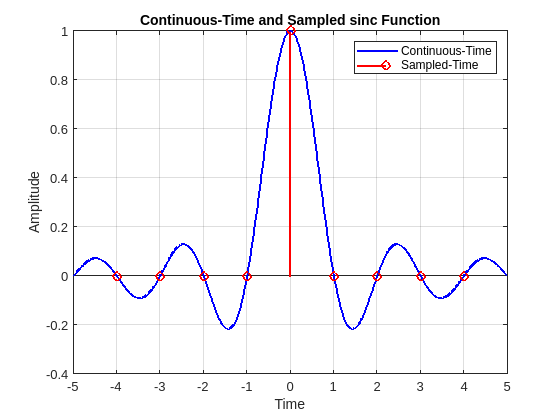

hold on;                                        % Hold the plot for adding the sampled signal
stem(n, h_sampled, 'r', 'LineWidth', 1.5);      % Plot sampled sinc function using stems
hold off;                                       % Release the plot
xlabel('Time');                                 % Label x-axis
ylabel('Amplitude');                            % Label y-axis
title('Continuous-Time and Sampled sinc Function'); % Add a title
legend('Continuous-Time', 'Sampled-Time');      % Add a legend
grid on;                                        % Enable grid